# P02: Funciones de membresía

## Objetivos

- Implementar operaciones de conjuntos difusos, utilizando MATLAB

- Implementar transformaciones de conjuntos difusos, utilizando MATLAB

## Implementación en MATLAB

MATLAB cuenta con la herramienta **Fuzzy Logic Toolbox (FLT)**, la documentación de cada función se puede consultar en el siguiente [enlace](https://www.mathworks.com/help/releases/R2020b/fuzzy/referencelist.html?type=function&s_tid=CRUX_topnav)

Una de las funciones implementada es la función de membresia **trimf**, para consultar la ayuda al respecto y su documentación.

help trimf

trimf - Triangular membership function

    This function computes fuzzy membership values using a triangular membership
    function.

    y = trimf(x,params)

    See also <a href="https://www.mathworks.com/help/releases/R2020b/fuzzy/dsigmf.html">dsigmf</a>, <a href="https://www.mathworks.com/help/releases/R2020b/fuzzy/gauss2mf.html">gauss2mf</a>, <a href="https://www.mathworks.com/help/releases/R2020b/fuzzy/gaussmf.html">gaussmf</a>, <a href="https://www.mathworks.com/help/releases/R2020b/fuzzy/gbellmf.html">gbellmf</a>, <a href="https://www.mathworks.com/help/releases/R2020b/fuzzy/pimf.html">pimf</a>, <a href="https://www.mathworks.com/help/releases/R2020b/fuzzy/psigmf.html">psigmf</a>, <a href="https://www.mathworks.com/help/releases/R2020b/fuzzy/sigmf.html">sigmf</a>, <a href="https://www.mathworks.com/help/releases/R2020b/fuzzy/smf.html">smf</a>, 
        <a href="https://www.mathworks.com/help/releases/R2020b/fuzzy/trapmf.html">trapmf</a>, <a href="https://www.mathworks.com/hel

doc trimf

La definición matemática de esta función según FLT de  MATLAB es


$$f(x ; a, b, c)=\left\{\begin{array}{cl}
0, & x \leq a \\
\frac{x-a}{b-a}, & a \leq x \leq b \\
\frac{c-x}{c-b}, & b \leq x \leq c \\
0, & c \leq x
\end{array}\right.$$


de forma equivalente 


$$f(x ; a, b, c)=\max \left(\min \left(\frac{x-a}{b-a}, \frac{c-x}{c-b}\right), 0\right)$$


Despues de consultar la documentación se implementa la siguiente gráfica

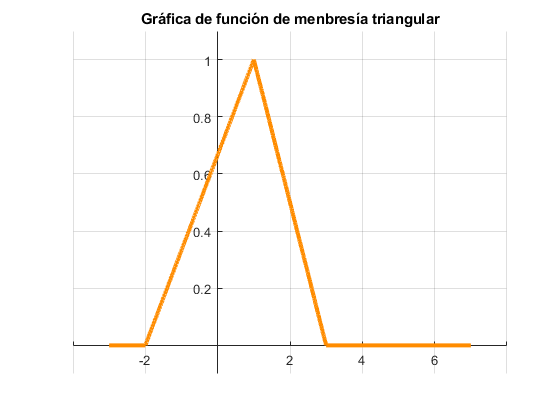

x=-3:0.001:7;
y=trimf(x,[-2, 1 3]);
plot(x, y, 'Color',[1 0.55 0], 'LineWidth', 3)
grid on
title("Gráfica de función de menbresía triangular")
axis([-4,8,-0.1,1.1])
h = gca;                             % ejes actuales
h.XAxisLocation = "origin";          % eje en el origen
h.YAxisLocation = "origin";          % eje en el origen
h.Box = "off";                       % apagar caja

De igualmanera se tienen las siguientes funciones de membresia implementadas

- trapmf

- gbellmf

- trimf

- gaussmf

- gauss2mf

- smf

- zmf

- psigmf

- dsigmf

- pimf

- sigmf 

 En la ayuda de MATLAB se puede encontrar una descripción de cada una de estas funciones así como ejemplos de gráficas, la siguiente gráfica muestra estos ejemplos 

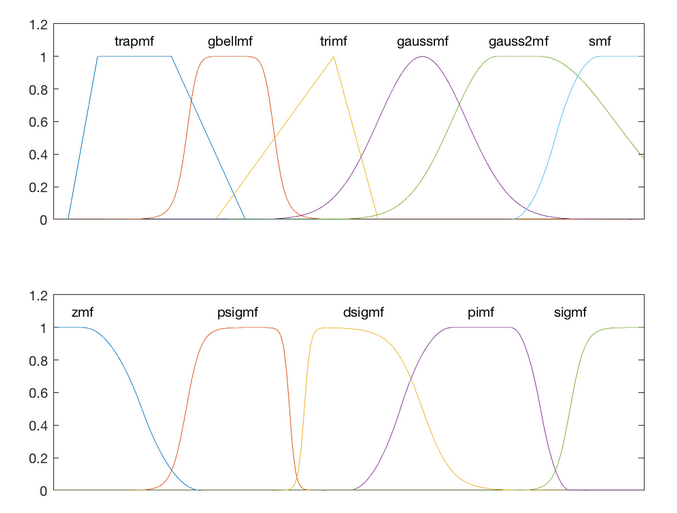

El código con el que se generan estas graficas se encuentra en el siguiente [enlace](https://www.mathworks.com/help/releases/R2020b/fuzzy/membership-function-gallery.html)

Con la función ***mfedit*** se puede tener una alternativa para editar las funciones de membresía. 

### Operaciones con conjuntos difusos dominio continuo

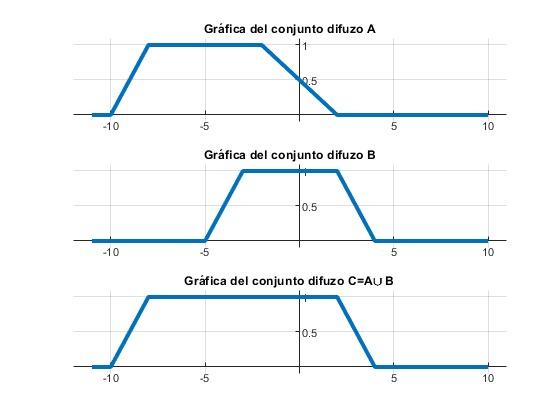

x = -11:0.1:10;
A = trapmf(x,[-10 -8 -2 2]);
B = trapmf(x,[-5 -3 2 4]);
C = max(A, B);                       % Unión estándar

figure
subplot(3,1,1)
plot(x,A,'LineWidth',3);
grid on
axis([-12,11,-0.1,1.1])
title('Gráfica del conjunto difuzo A')
h = gca;                             % ejes actuales
h.XAxisLocation = "origin";          % eje en el origen
h.YAxisLocation = "origin";          % eje en el origen
h.Box = "off"; 

subplot(3,1,2)
plot(x,B,'LineWidth',3);
grid on
axis([-12,11,-0.1,1.1])
title('Gráfica del conjunto difuzo B')
h = gca;                             % ejes actuales
h.XAxisLocation = "origin";          % eje en el origen
h.YAxisLocation = "origin";          % eje en el origen
h.Box = "off"; 

subplot(3,1,3)
plot(x,C,'LineWidth',3);
grid on
axis([-12,11,-0.1,1.1])
title('Gráfica del conjunto difuzo C=A\cup B')
h = gca;                             % ejes actuales
h.XAxisLocation = "origin";          % eje en el origen
h.YAxisLocation = "origin";          % eje en el origen
h.Box = "off"; 

### Operaciones con conjuntos difusos dominio discreto.

Si suponemos que tenemos los siguientes conjuntos difusos discretos 


$${A}=\left\{\frac{0.15}{1}+\frac{0.25}{2}+\frac{0.6}{3}+\frac{0.9}{4}\right\} \quad B=\left\{\frac{0.2}{1}+\frac{0.3}{2}+\frac{0.5}{3}+\frac{0.8}{4}\right\}$$


Gráficamos estos conjuntos discreto

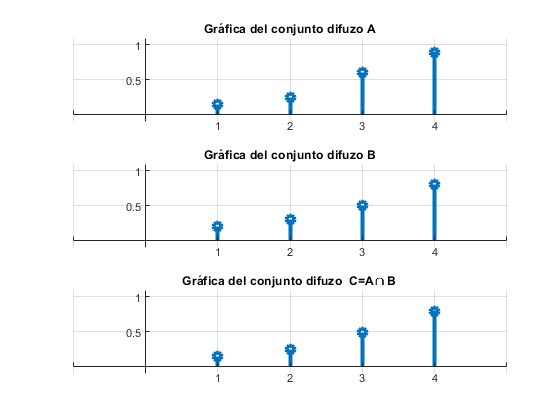

x = 1:4;
A = [0.15,0.25,0.6,0.9];
B = [0.2,0.3,0.5,0.8];
C = min(A, B);                       % Intersección estándar

figure
subplot(3,1,1)
stem(x,A,'LineWidth',3);
grid on
axis([-1,5,-0.1,1.1])
title('Gráfica del conjunto difuzo A')
h = gca;                             % ejes actuales
h.XAxisLocation = "origin";          % eje en el origen
h.YAxisLocation = "origin";          % eje en el origen
h.Box = "off"; 

subplot(3,1,2);
stem(x,B,'LineWidth',3);
grid on
axis([-1,5,-0.1,1.1])
title('Gráfica del conjunto difuzo B')
h = gca;                             % ejes actuales
h.XAxisLocation = "origin";          % eje en el origen
h.YAxisLocation = "origin";          % eje en el origen
h.Box = "off";
 
subplot(3,1,3)
stem(x,C,'LineWidth',3);
grid on
axis([-1,5,-0.1,1.1])
title('Gráfica del conjunto difuzo  C=A\cap B')
h = gca;                             % ejes actuales
h.XAxisLocation = "origin";          % eje en el origen
h.YAxisLocation = "origin";          % eje en el origen
h.Box = "off"; 

## Entregables

Se revisa una publicación (html) de la práctica. En este caso tendá que iniciar indicando el nombre de la práctica y sus datos personales, equipos de 3 a 5 personas (Portada). El índice lo genera MATLAB. Los objetivos deben ser incluidos y se han presentado al principio de la práctica.

Como introducciòn de una breve introducciòn de que son lso conjuntos difuzos y el porque parecen una buena alternativa para modelar ciertos tipos de problemas. Para esto, puedes apoyarte de los que ya sabes, en particular con la información consultada en el reporte uno (R01) y el reporte dos (R02).

Para el desarrollo se tienen que resolver cada uno de los siguientes problemas comenzando una nueva sección (para la publicación) en cada uno de ellos.

### Problema 1

Investiga la expresión matemática para la función  smf y la función psigmf. Reporta dichas expresiones 

### Problema 2

Cree una función en matlab que reciba como argumentos de entrada el dominio y el rango de una función de membresía, esta función debe crear la grafica del conjunto difuso con una edición de tu preferencia (no queremos repetir los códigos para gráficar cada vez que se quiera visualizar un conjunto difuzo, como se ha visto previamente).

Prueba el código con las dos funciones del problema anterior, los parámetros que debes utilizar  (debes investigar) son los que se usan en el ejemplo de la práctica. 

Se espera esta sección dos llamadas a la función con las dos gráficas respectivas. 

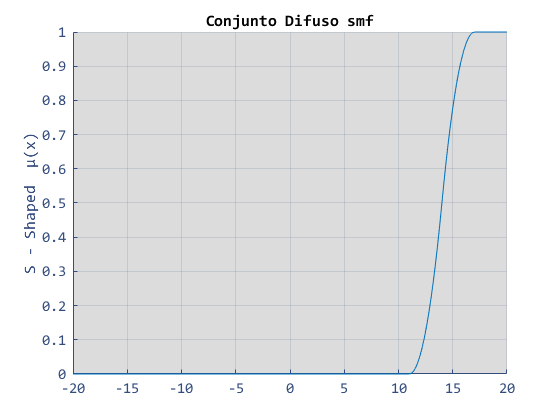

x=linspace(-20,20,201);
py1=2;
save('dimP1.mat',"py1")
y1=smf(x,[11 17]);
plotFuzzy(x,y1);

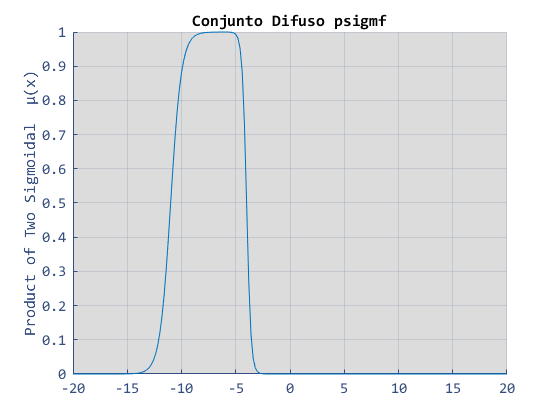

py1=4;
save('dimP1.mat',"py1")
y2=psigmf(x,[2 -11 -5 -4]);
plotFuzzy(x,y2);

### Problema 3 

Repite el problema anterior pero para conjuntos difusos en tiempo discreto.  

Prueba esta función con los conjuntos difusos (A, B) de la imagen 5 (OperDif5). de las notas *NO2. Operaciones difusas que se encuentran en* la página del curso.

Se espera esta sección dos llamadas a la función con las dos gráficas respectivas. 

### Problema 4

Elabora una función que reciba el conjunto dominio x y el rango A de un conjunto difuso. Un parámetro adicional que indique el tipo de complemento que se quiere hacer (estándar, Sugeno, Yager). La función debe regresar el rango de valores del conjunto resultante C. Además de imprimir una figura (2 por 1) donde se muestren las grafica de los dos conjunto involucrados.

Prueba esta función con el inciso a) de la imagen 4 (OperDif4). de las notas *NO2. Operaciones difusas que se encuentran en* la página del curso. Para esto:

- Reporta los tres tipos de complementos (si no puedes implentar esto es una solo función crea tres funciones de complemento difuso)

- Combina las herramientas que ya tienes desarrolladas (de ser posible) para mostrar una gráfica con los tres tipos de complementos o desarrolla esta gráfica sin utilizar tus herramientas

En esta sección se espera tres llamadas a la función y un código para generar la cuarta gráfica. 

### Problema 5 

Elabora una función que reciba el conjunto dominio x, el rango A, el rango B, de dos conjunto difusos. Un parámetro adicional que indique el tipo de intersección que se quiere hacer (míninimo, producto algebraico, producto acotado). La función debe regresar el rango de valores del conjunto resultante C. Además de imprimir una figura (3 por 1) donde se muestren las grafica de los tres conjunto involucrados.

Prueba esta función con el inciso c) de la imagen 4 (OperDif4). de las notas *NO2. Operaciones difusas que se encuentran en* la página del curso. Para esto:

- Reporta los tres tipos de intersecciones

- Combina las herramientas que ya tienes desarrolladas (de ser posible) para mostrar una gráfica con los tres tipos de intersecciones o desarrolla esta gráfica sin utilizar tus herramientas

En esta sección se espera tres llamadas a la función y un código para generar la cuarta gráfica. 

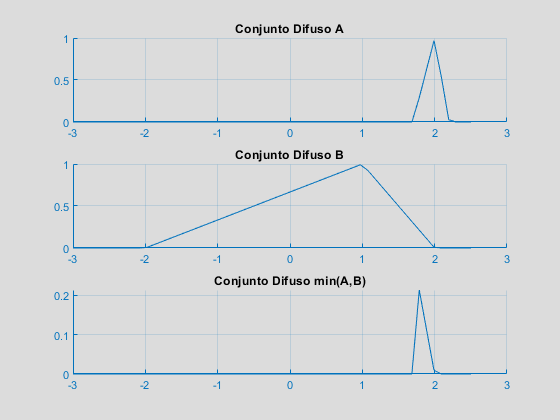

x=linspace(-3,2.5,55);
yA=memFuncA(x);
yB=memFuncB(x);
interFunc(x,yA,yB,'min');

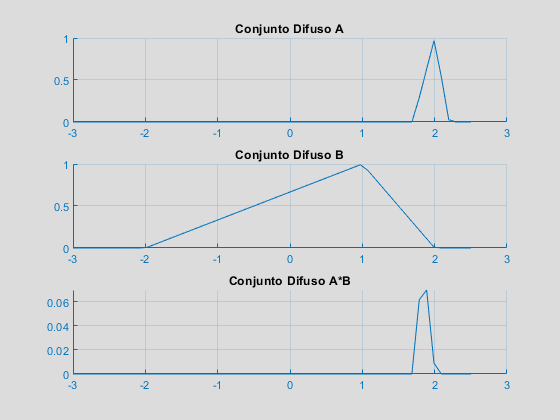


interFunc(x,yA,yB,'alg');

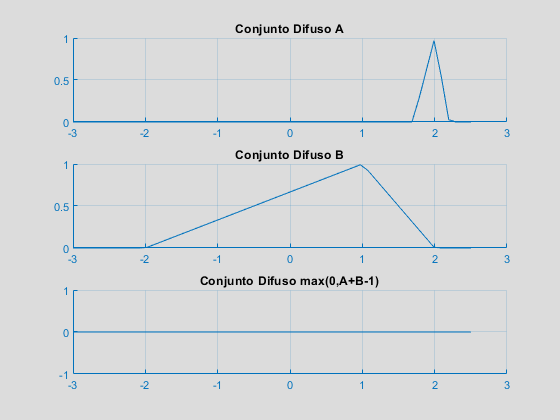

interFunc(x,yA,yB,'aco');

Generando el conjunto A∩B 

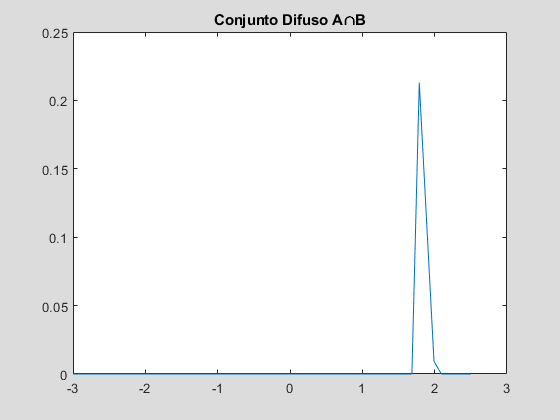

x=linspace(-3,2.5,55);
A=memFuncA(x);
B=memFuncB(x);
C=min(A,B);
subplot(1,1,1)
plot(x,C);
title('Conjunto Difuso A∩B');

### Problema 6

Elabora una función que reciba el conjunto dominio x, el rango A, el rango B, de dos conjunto difusos. Un parámetro adicional que indique el tipo de unión que se quiere hacer (máximo, suma algebraica, suma acotada). La función debe regresar el rango de valores del conjunto resultante C. Además de imprimir una figura (3 por 1) donde se muestren las grafica de los tres conjunto involucrados.

Prueba esta función con el inciso d) de la imagen 4 (OperDif4). de las notas *NO2. Operaciones difusas que se encuentran en* la página del curso. Para esto:

- Reporta los tres tipos de uniones

- Combina las herramientas que ya tienes desarrolladas (de ser posible) para mostrar una gráfica con los tres tipos de uniones o desarrolla esta gráfica sin utilizar tus herramientas

En esta sección se espera tres llamadas a la función y un código para generar la cuarta gráfica. 

### Problema 7.

Resuleve el problema 4 para conjuntos en tiempo discreto. Prueba esta función con el inciso a) de la imagen 5 (OperDif5). 

### Problema 8.

Resuleve el problema 5 para conjuntos en tiempo discreto. Prueba esta función con el inciso c) de la imagen 5 (OperDif5). 

### Problema 9.

Resuleve el problema 6 para conjuntos en tiempo discreto. Prueba esta función con el inciso d) de la imagen 5 (OperDif5). 

### Problema 10

Implemente tres funciones,  para calcular las siguientes funciones de membresia

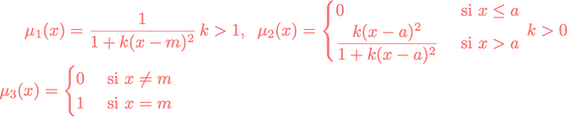

Los párametros que no muestras restricción pueden tener cualquier numero real como argumento, la función debe ser capaz de evaluar vectores de cualquier dimensión. La función $\mu_3
$ recibe el nombre de singleton

Grafique las funciones para los siguintes parámetros (con las herramientas ya construidas)

x=linspace(-10,10,50);

(a) $$\mu_1(x)\,con \, m=1,\,k=2$, (b) $\mu_1(x)\,con \, m=2,\,k=4$$

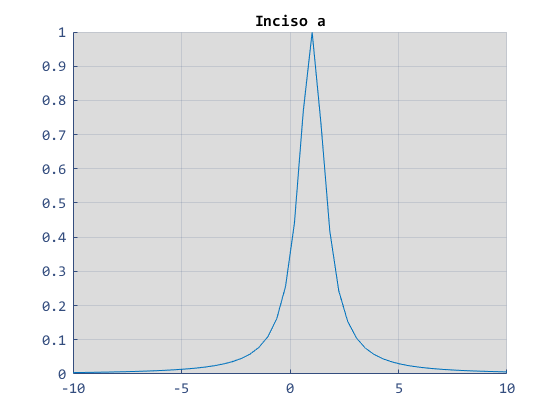

memFun1(x,1,2);

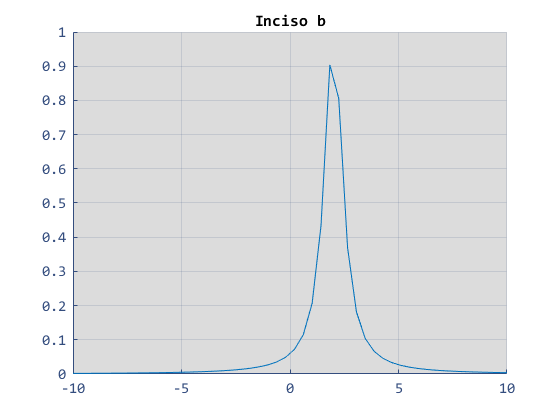

memFun1(x,2,4);


$$(c) \mu_2(x)\,con\, a=1,\,k=2, (d) \mu_2(x)\,con\, a=2\,k=4$$


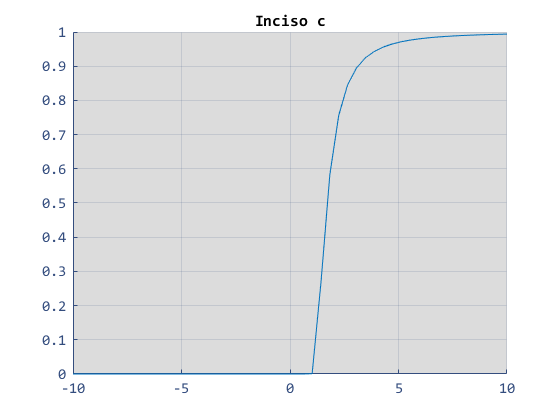

memFun2(x,1,2);

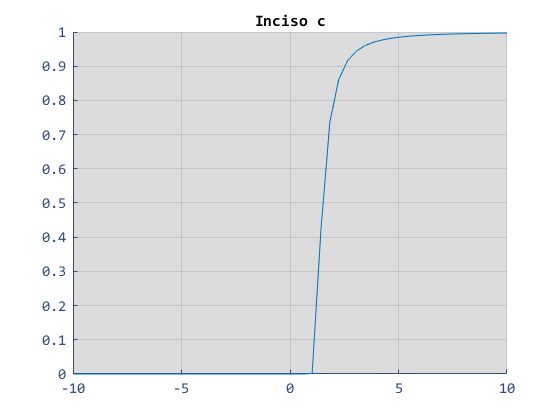

memFun2(x,2,4);


$$(e) \mu_3(x)\,con\, m=2$$


x=[-3:3]

x =     -3    -2    -1     0     1     2     3


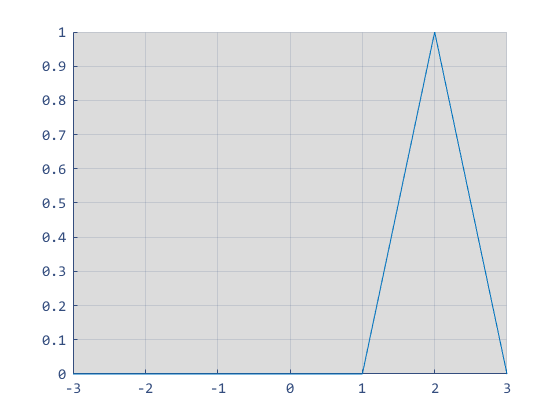

memFun3(x,2);

Para ello proponga el dominio x. Se esperan 5 gráficas con el código correspndiente para generarlas.

### Problema 11

Implemente una gráfica donde indique ejemplos especificos para ilustrar

 

### Problema 12

Escoja tres conjuntos difusos $A,B,C$ con dominuo continuo. La elección debe ser de tal forma que la itersección de B con A y de B con C sea no vacia (esto solo es solo para visulizar la operación, y solo para eso)

 verifique las siguientes propiedades

 

Para la verificación, elabore la gráfica de los conjuntos de cada lado de la igualdad y posteriormente observe que el resultado gráfico es el mismo. 

No es necesario incluir conclusiones en esta práctica, si lo considera necesario puede incluir apéndices, no olvide incluir sus referencias. 